# Exercise 1 - Pixels and quantization

close all;
set(groot,'defaultFigurePosition',[80 80 740 560]);
set(groot,'defaultAxesFontSize',10);
format short g;
% Load the image and report the size and data class.
% Look for MATLAB's bundled sample image, even if the imdata directory
% is not on MATLAB's current search path.
if isempty(ver('images'))
    error(['Image Processing Toolbox is not installed. Install it from ' ...
           'MATLAB Home > Add-Ons, then rerun this script.']);
end
sampleFolders = {pwd, fullfile(matlabroot,'toolbox','images','imdata'), ...
    fullfile(matlabroot,'toolbox','images','imdemos')};
camFile = 'cameraman.tif';
for f = 1:numel(sampleFolders)
    candidate = fullfile(sampleFolders{f},'cameraman.tif');
    if isfile(candidate), camFile = candidate; break; end
end
if ~isfile(camFile)
    error(['Cannot locate cameraman.tif. Check Image Processing Toolbox ' ...
           'or the MATLAB example-image folders.']);
end
I = imread(camFile);
disp(['Loaded cameraman.tif from: ' camFile]);

Loaded cameraman.tif from: C:\Program Files\MATLAB\R2025b\toolbox\images\imdata\cameraman.tif


disp('Exercise 1: cameraman.tif');

Exercise 1: cameraman.tif


disp(['Image size: ' mat2str(size(I))]);

Image size: [256 256]


disp(['Image class: ' class(I)]);

Image class: uint8


% Quantization: 4 bits = 16 levels; 2 bits = 4 levels; 1 bit = 2 levels.
% Conversion is kept in [0,1] to avoid an overflow in uint8.
Id = im2double(I);
q4 = floor(Id * 16) / 15;
q2 = floor(Id * 4) / 3;
q1 = floor(Id * 2) / 1;
q4 = min(q4,1); q2 = min(q2,1); q1 = min(q1,1);
% Direct indexing skips pixels; imresize with bicubic interpolation uses
% antialiasing when it reduces the image size.
manualSmall = I(1:8:end,1:8:end);
resizedSmall = imresize(I,1/8,'bicubic');
manualDisplay = imresize(manualSmall,size(I),'nearest');
resizeDisplay = imresize(resizedSmall,size(I),'nearest');
disp(['Direct subsampling size: ' mat2str(size(manualSmall))]);

Direct subsampling size: [32 32]


disp(['imresize subsampling size: ' mat2str(size(resizedSmall))]);

imresize subsampling size: [32 32]


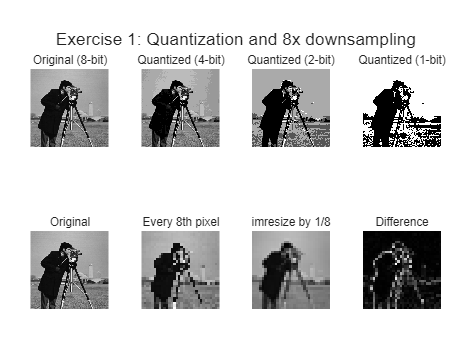

figure('Name','Exercise 1','NumberTitle','off');
theme(gcf,'light');
tiledlayout(2,4,'TileSpacing','compact','Padding','compact');
nexttile; imshow(I); title('Original (8-bit)');
nexttile; imshow(q4); title('Quantized (4-bit)');
nexttile; imshow(q2); title('Quantized (2-bit)');
nexttile; imshow(q1); title('Quantized (1-bit)');
nexttile; imshow(I); title('Original');
nexttile; imshow(manualDisplay); title('Every 8th pixel');
nexttile; imshow(resizeDisplay); title('imresize by 1/8');
nexttile; imshow(abs(double(manualDisplay)-double(resizeDisplay)),[]);
title('Difference');
sgtitle('Exercise 1: Quantization and 8x downsampling');

drawnow; pause(0.5);
% Think about: At 1 bit the main silhouette is usually still visible,
% but much of the fine detail is lost. Aliasing is clearest in direct
% subsampling, especially on fine textures and diagonal structures.

## Exercise 2 - Degrade an image

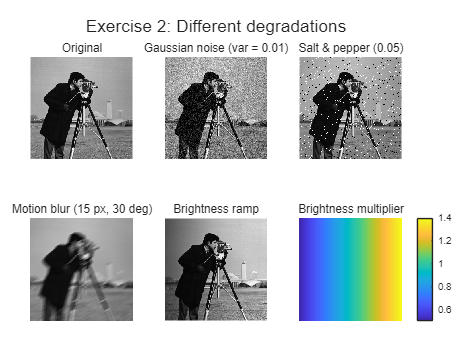

rng(42,'twister'); % make the noise reproducible
noiseGaussian = imnoise(I,'gaussian',0,0.01);
noiseSP = imnoise(I,'salt & pepper',0.05);
H = fspecial('motion',15,30);
imageMotion = imfilter(I,H,'replicate','conv');
[rows,cols] = size(I);
ramp = repmat(linspace(0.5,1.4,cols),rows,1);
imageRamp = im2uint8(min(1,max(0,im2double(I).*ramp)));
figure('Name','Exercise 2','NumberTitle','off');
theme(gcf,'light');
tiledlayout(2,3,'TileSpacing','compact','Padding','compact');
nexttile; imshow(I); title('Original');
nexttile; imshow(noiseGaussian); title('Gaussian noise (var = 0.01)');
nexttile; imshow(noiseSP); title('Salt & pepper (0.05)');
nexttile; imshow(imageMotion); title('Motion blur (15 px, 30 deg)');
nexttile; imshow(imageRamp); title('Brightness ramp');
nexttile; imagesc(ramp); axis image off; colorbar; title('Brightness multiplier');
sgtitle('Exercise 2: Different degradations');

drawnow; pause(0.5);
% Think about: Gaussian noise is additive, salt & pepper replaces pixels,
% the brightness ramp is multiplicative, and motion blur is convolutional.
% Median filtering removes isolated salt & pepper outliers effectively.

## Exercise 3 - Contrast and geometry

poutFile = 'pout.tif';
for f = 1:numel(sampleFolders)
    candidate = fullfile(sampleFolders{f},'pout.tif');
    if isfile(candidate), poutFile = candidate; break; end
end
if ~isfile(poutFile)
    error('Cannot locate pout.tif. Check the MATLAB sample image folders.');
end
P = imread(poutFile);
disp(['Exercise 3: pout.tif, image size ' mat2str(size(P))]);

Exercise 3: pout.tif, image size [291 240]


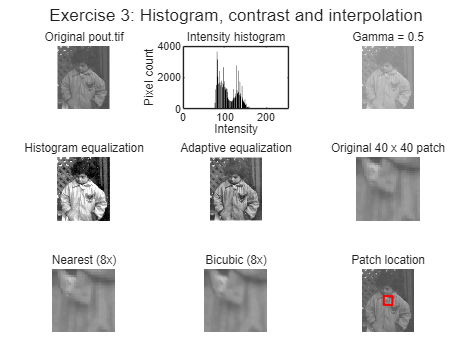

Pg = imadjust(P,[],[],0.5);
Ph = histeq(P);
Pa = adapthisteq(P);
% Take a centered, exactly 40-by-40-pixel image patch and enlarge it 8x.
pr = floor((size(P,1)-40)/2)+1;
pc = floor((size(P,2)-40)/2)+1;
patch = P(pr:pr+39,pc:pc+39);
nearestPatch = imresize(patch,8,'nearest');
bicubicPatch = imresize(patch,8,'bicubic');
figure('Name','Exercise 3','NumberTitle','off');
theme(gcf,'light');
tiledlayout(3,3,'TileSpacing','compact','Padding','compact');
nexttile; imshow(P); title('Original pout.tif');
nexttile; [histCounts,histLevels] = imhist(P);
bar(histLevels,histCounts,1,'k'); xlim([0 255]); title('Intensity histogram');
xlabel('Intensity'); ylabel('Pixel count');
nexttile; imshow(Pg); title('Gamma = 0.5');
nexttile; imshow(Ph); title('Histogram equalization');
nexttile; imshow(Pa); title('Adaptive equalization');
nexttile; imshow(patch); title('Original 40 x 40 patch');
nexttile; imshow(nearestPatch); title('Nearest (8x)');
nexttile; imshow(bicubicPatch); title('Bicubic (8x)');
nexttile; imshow(P); hold on;
rectangle('Position',[pc pr 40 40],'EdgeColor','r','LineWidth',1.5);
hold off; title('Patch location');
sgtitle('Exercise 3: Histogram, contrast and interpolation');

drawnow; pause(0.5);
% Think about: Adaptive equalization improves local detail, while gamma 0.5
% brightens because sqrt(x) > x for 0 < x < 1 (histeq may overemphasize contrast).
% Bicubic gives smoother transitions than blocky nearest-neighbor replication.

## Exercise 4 - Filter and compare

Use the two noisy images created in Exercise 2.

k = fspecial('average',[3 3]);
gaussianMean = imfilter(noiseGaussian,k,'replicate');
gaussianGauss = imgaussfilt(noiseGaussian,1,'Padding','replicate');
gaussianMedian = medfilt2(noiseGaussian,[3 3],'symmetric');
spMean = imfilter(noiseSP,k,'replicate');
spGauss = imgaussfilt(noiseSP,1,'Padding','replicate');
spMedian = medfilt2(noiseSP,[3 3],'symmetric');
% Six PSNR values measured against the ORIGINAL image.
psnrValues = [psnr(gaussianMean,I) psnr(gaussianGauss,I) psnr(gaussianMedian,I); ...
              psnr(spMean,I)       psnr(spGauss,I)       psnr(spMedian,I)];
PSNR_table = array2table(psnrValues,'VariableNames',{'Mean_dB','Gaussian_dB','Median_dB'}, ...
    'RowNames',{'Gaussian_noise','SaltPepper_noise'});
disp('Exercise 4: PSNR values (dB); larger is better');

Exercise 4: PSNR values (dB); larger is better


disp(PSNR_table);

                        Mean_dB    Gaussian_dB    Median_dB
                        _______    ___________    _________

    Gaussian_noise      24.347        24.78        24.228  
    SaltPepper_noise    23.543       24.053        26.887  



filterNames = {'Mean','Gaussian','Median'};
[~,winGaussian] = max(psnrValues(1,:));
[~,winSP] = max(psnrValues(2,:));
disp(['Best Gaussian-noise PSNR: ' filterNames{winGaussian}]);

Best Gaussian-noise PSNR: Gaussian


disp(['Best salt-and-pepper PSNR: ' filterNames{winSP}]);

Best salt-and-pepper PSNR: Median


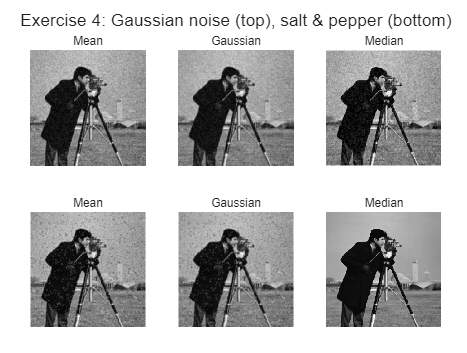

% Use a common display scale for a fair frequency-spectrum comparison.
Soriginal = log(1+abs(fftshift(fft2(im2double(I)))));
Smotion = log(1+abs(fftshift(fft2(im2double(imageMotion)))));
commonLimits = [min([Soriginal(:);Smotion(:)]),max([Soriginal(:);Smotion(:)])];
figure('Name','Exercise 4','NumberTitle','off');
theme(gcf,'light');
tiledlayout(2,3,'TileSpacing','compact','Padding','compact');
nexttile; imshow(gaussianMean); title('Mean');
nexttile; imshow(gaussianGauss); title('Gaussian');
nexttile; imshow(gaussianMedian); title('Median');
nexttile; imshow(spMean); title('Mean');
nexttile; imshow(spGauss); title('Gaussian');
nexttile; imshow(spMedian); title('Median');
sgtitle('Exercise 4: Gaussian noise (top), salt & pepper (bottom)');

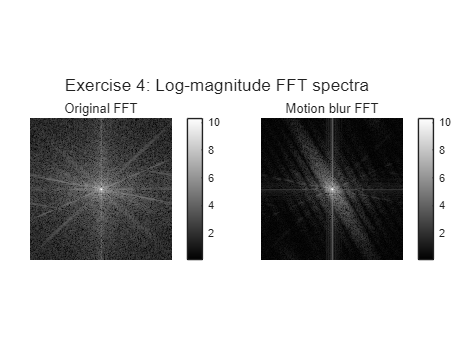

drawnow; pause(0.5);
figure('Name','Exercise 4 - FFT spectra','NumberTitle','off');
theme(gcf,'light');
tiledlayout(1,2,'TileSpacing','compact','Padding','compact');
nexttile; imagesc(Soriginal,commonLimits); axis image off;
colormap(gray); colorbar; title('Original FFT');
nexttile; imagesc(Smotion,commonLimits); axis image off;
colormap(gray); colorbar; title('Motion blur FFT');
sgtitle('Exercise 4: Log-magnitude FFT spectra');

drawnow; pause(0.5);
fprintf('Think about: Best for Gaussian noise: %s.\n',filterNames{winGaussian});

Think about: Best for Gaussian noise: Gaussian.


fprintf('Best for salt & pepper: %s (measured PSNR).\n',filterNames{winSP});

Best for salt & pepper: Median (measured PSNR).


% Motion blur suppresses high frequencies and introduces directional bands.

## Exercise 5 - Edges

edgesSobel = edge(I,'sobel');
[edgeC1,cannyThreshold] = edge(I,'canny',[],1);
fprintf('Sobel edge pixels: %d\n',nnz(edgesSobel));

Sobel edge pixels: 2503


edgeC2 = edge(I,'canny',[],2);
edgeC3 = edge(I,'canny',[],3);
disp(['Canny edge pixels, sigma=1: ' num2str(nnz(edgeC1))]);

Canny edge pixels, sigma=1: 7816


disp(['Canny edge pixels, sigma=2: ' num2str(nnz(edgeC2))]);

Canny edge pixels, sigma=2: 4413


disp(['Canny edge pixels, sigma=3: ' num2str(nnz(edgeC3))]);

Canny edge pixels, sigma=3: 2780


% Even baseline Canny has internal Gaussian smoothing. The second case
% adds an explicit preprocessing smoothing step for comparison.
noisyCanny = edge(noiseGaussian,'canny',cannyThreshold,1);
preSmoothed = imgaussfilt(noiseGaussian,1.5);
smoothedCanny = edge(preSmoothed,'canny',cannyThreshold,1);
countNoisy = nnz(noisyCanny);
countSmoothed = nnz(smoothedCanny);
% A pixel is an approximate false edge if it is more than one pixel away
% from the clean-image reference edge map (3x3 spatial tolerance).
referenceEdge = edgeC1;
fprintf('Fixed Canny thresholds for noise comparison: %.5f, %.5f\n',cannyThreshold);

Fixed Canny thresholds for noise comparison: 0.03125, 0.07812


referenceTolerance = imdilate(referenceEdge,strel('square',3));
falseBefore = nnz(noisyCanny & ~referenceTolerance);
falseAfter = nnz(smoothedCanny & ~referenceTolerance);
falseRemoved = falseBefore - falseAfter;
disp('Exercise 5: Noisy-image Canny results');

Exercise 5: Noisy-image Canny results


disp(['Edge pixels without extra smoothing: ' num2str(countNoisy)]);

Edge pixels without extra smoothing: 22457


disp(['Edge pixels with extra smoothing: ' num2str(countSmoothed)]);

Edge pixels with extra smoothing: 13250


disp(['Approx. false-edge pixels before smoothing: ' num2str(falseBefore)]);

Approx. false-edge pixels before smoothing: 14221


disp(['Approx. false-edge pixels after smoothing: ' num2str(falseAfter)]);

Approx. false-edge pixels after smoothing: 7275


disp(['Net approximate false-edge pixels removed: ' num2str(falseRemoved)]);

Net approximate false-edge pixels removed: 6946


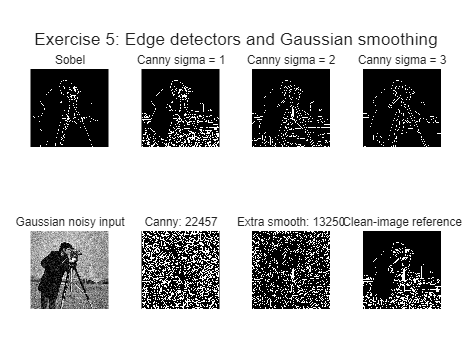

figure('Name','Exercise 5','NumberTitle','off');
theme(gcf,'light');
tiledlayout(2,4,'TileSpacing','compact','Padding','compact');
nexttile; imshow(edgesSobel); title('Sobel');
nexttile; imshow(edgeC1); title('Canny sigma = 1');
nexttile; imshow(edgeC2); title('Canny sigma = 2');
nexttile; imshow(edgeC3); title('Canny sigma = 3');
nexttile; imshow(noiseGaussian); title('Gaussian noisy input');
nexttile; imshow(noisyCanny); title(['Canny: ' num2str(countNoisy)]);
nexttile; imshow(smoothedCanny); title(['Extra smooth: ' num2str(countSmoothed)]);
nexttile; imshow(referenceEdge); title('Clean-image reference');
sgtitle('Exercise 5: Edge detectors and Gaussian smoothing');

drawnow; pause(0.5);
% Think about: Increasing sigma suppresses noise and fine edges, but can
% also remove genuine weak details. The signed falseRemoved estimate uses
% fixed thresholds and a one-pixel Chebyshev tolerance around clean edges;
% weak real edges absent from the reference can still be counted as false.

## Exercise 6 - Segment and measure

coinsFile = 'coins.png';
for f = 1:numel(sampleFolders)
    candidate = fullfile(sampleFolders{f},'coins.png');
    if isfile(candidate), coinsFile = candidate; break; end
end
if ~isfile(coinsFile)
    error('Cannot locate coins.png. Check the MATLAB sample image folders.');
end
C = imread(coinsFile);
if size(C,3) == 3
    C = rgb2gray(C);
end
otsuThreshold = graythresh(C);
BW = imbinarize(C,otsuThreshold);
% Make the background black if the four image corners are mostly white.
if mean(double(BW([1 end],[1 end])),'all') > 0.5
    BW = ~BW;
end
% Fill first: opening the unfilled mask destroys the dim coin's thin rim.
BWprefilled = imfill(BW,'holes');
% Opening then removes speckles without losing the enclosed coin interior.
BWopened = imopen(BWprefilled,strel('disk',2));
% Fill again after opening to repair any remaining enclosed holes.
BWfilled = imfill(BWopened,'holes');
% Remove tiny remaining disconnected white components (not coins).
BWclean = bwareaopen(BWfilled,100);
CC = bwconncomp(BWclean,8);
stats = regionprops(CC,'Area','Centroid','BoundingBox','Solidity');
areas = [stats.Area]';
coinIds = (1:CC.NumObjects)';
Area_table = table(coinIds,areas,'VariableNames',{'Coin_ID','Area_pixels'});
disp(['Exercise 6: Otsu threshold = ' num2str(otsuThreshold,4)]);

Exercise 6: Otsu threshold = 0.4941


disp(['Connected coin regions found: ' num2str(CC.NumObjects)]);

Connected coin regions found: 10


disp(Area_table);

    Coin_ID    Area_pixels
    _______    ___________

       1          2651    
       2          1852    
       3          2680    
       4          1810    
       5          2753    
       6          2510    
       7          2594    
       8          2544    
       9          1893    
      10          1864    



if ~isempty(stats)
    [largestArea,largestID] = max(areas);
    disp(['Largest region: coin ' num2str(largestID) ...
          ', area = ' num2str(largestArea) ' pixels']);
end

Largest region: coin 5, area = 2753 pixels


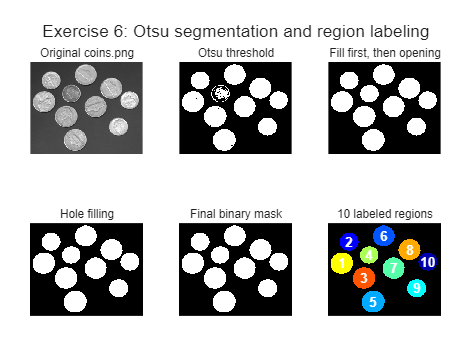

L = labelmatrix(CC);
RGB = label2rgb(L,'jet','k','shuffle');
figure('Name','Exercise 6','NumberTitle','off');
theme(gcf,'light');
tiledlayout(2,3,'TileSpacing','compact','Padding','compact');
nexttile; imshow(C); title('Original coins.png');
nexttile; imshow(BW); title('Otsu threshold');
nexttile; imshow(BWopened); title('Fill first, then opening');
nexttile; imshow(BWfilled); title('Hole filling');
nexttile; imshow(BWclean); title('Final binary mask');
nexttile; imshow(RGB); title([num2str(CC.NumObjects) ' labeled regions']);
hold on;
for index = 1:CC.NumObjects
    xy = stats(index).Centroid;
    text(xy(1),xy(2),num2str(index),'Color','white', ...
        'FontSize',10,'FontWeight','bold','HorizontalAlignment','center');
end
hold off;
sgtitle('Exercise 6: Otsu segmentation and region labeling');

drawnow; pause(0.5);
% Think about: Opening removes speckles and thin bridges, filling restores
% enclosed dark interiors, and bwareaopen removes remaining tiny components.
% Touching coins merge whenever their final masks remain connected.

% Inspect boundaries on the input to check for missed or merged coins.
borderPixels = nnz(BWclean(1,:))+nnz(BWclean(end,:)) ...
    +nnz(BWclean(:,1))+nnz(BWclean(:,end));
fprintf('Foreground pixels on image border: %d\n',borderPixels);

Foreground pixels on image border: 0


fprintf('Region solidity range: %.3f to %.3f\n',min([stats.Solidity]),max([stats.Solidity]));

Region solidity range: 0.982 to 0.988


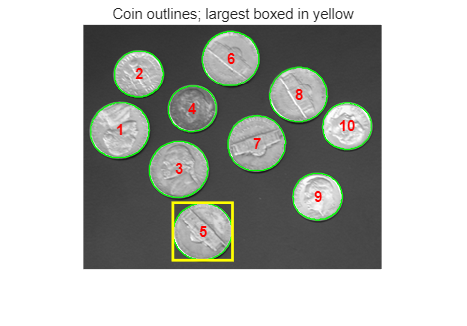

figure('Name','Exercise 6 - Segmentation inspection','NumberTitle','off');
theme(gcf,'light');
imshow(C); hold on;
boundaries = bwboundaries(BWclean,'noholes');
for index = 1:numel(boundaries)
    b = boundaries{index}; plot(b(:,2),b(:,1),'g','LineWidth',1);
    xy = stats(index).Centroid;
    text(xy(1),xy(2),sprintf('%d',index),'Color','r', ...
        'FontSize',11,'FontWeight','bold','HorizontalAlignment','center');
end
rectangle('Position',stats(largestID).BoundingBox, ...
    'EdgeColor','y','LineWidth',2);
hold off; title('Coin outlines; largest boxed in yellow');

drawnow; pause(0.5);


% Quality check: inspect all ten outlined coins against the source image;
% filling before opening preserves the darker coin and prevents underestimation.